# MATLAB® による宇宙のデータを用いたデータ解析入門

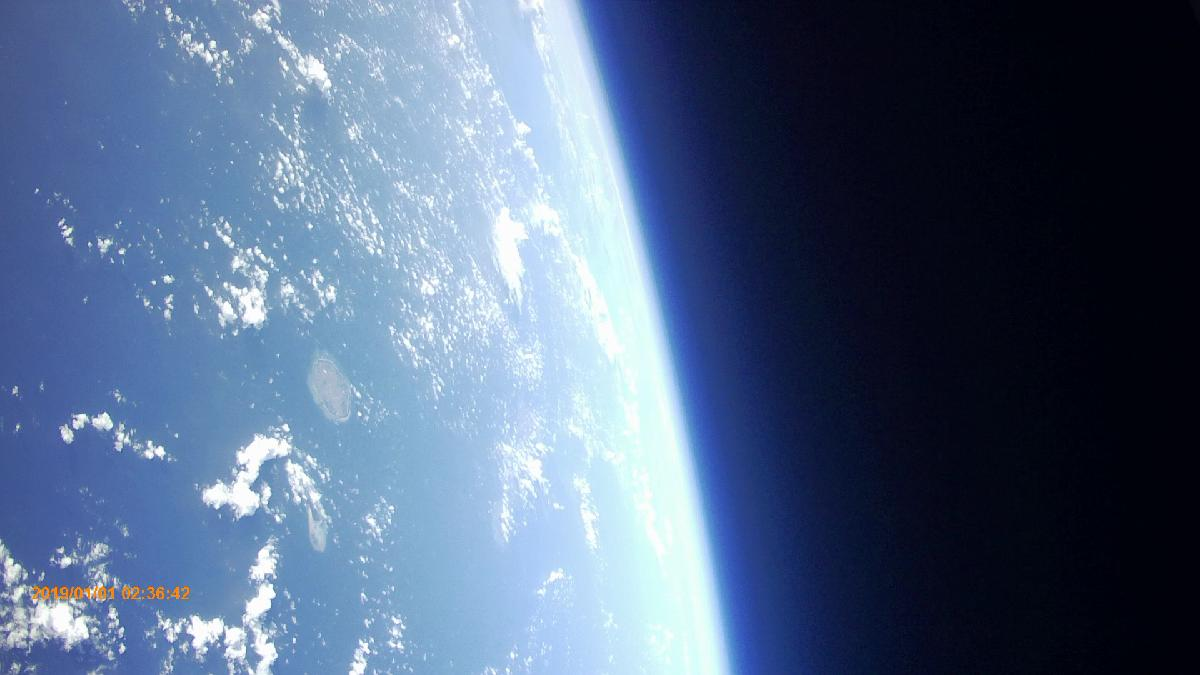

## e-kagakuアカデミー　×　MathWorks®

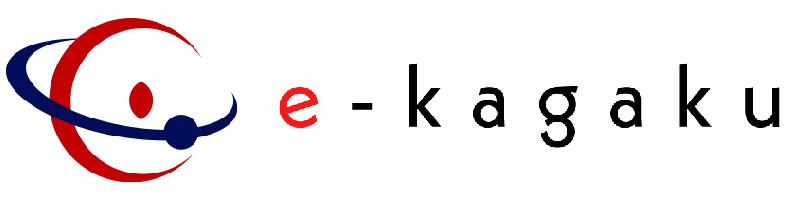　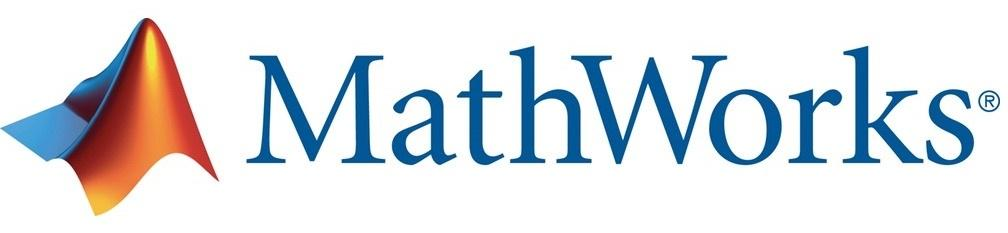

## **Mission2 気温の変化率を検証しよう**

Mission1 では，まずはデータ分析に必要な，データの抽出と可視化を行ってきました．Mission2 では，Mission1 で行ってきた データ抽出と可視化を駆使し，下記の課題に取り組みます．

一般にデータ解析を行う時，まずはデータに対し仮説を立てて，データが仮説通りなのか，異なるのか，確認するところから始めます．

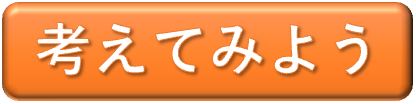

まずは，課題を解くために何が必要なのか，数人で話し合い，言葉で書いてみましょう．

言葉で表現できましたか？言葉で表現できたならば，実際にプログラムを書いてみましょう．

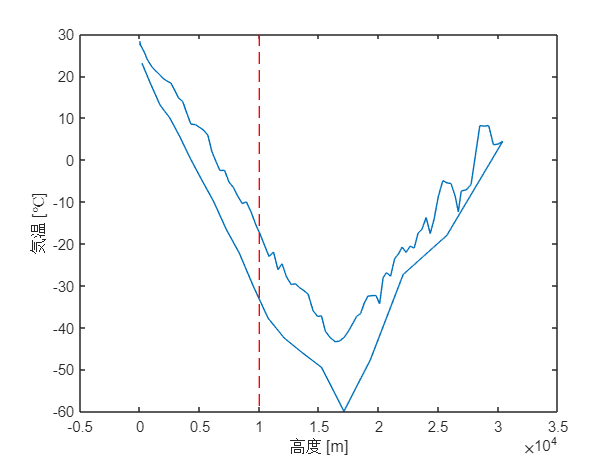

% プログラム例
data = readmatrix('flight_data.xlsx');  % データをワークスペースに取り込み

altitude = data(:,2);   % 高度データを変数 altitude に代入
temp = data(:,4);       % 気温データを変数 temp に代入

plot(altitude,temp)     % 高度-気温データをグラフ化
xlabel("高度 [m]")
ylabel("気温 [℃]")

hold on
plot([10000 10000],[30 -60] ,'r--') % 高度 10000 m. 対流圏と成層圏の境界を赤線で表示
hold off

% プログラム例
% 変数 altitude から，対流圏を満たす 10000 m 以下のデータを抜き出す．
% まずは，find 関数を使い，最初に高度が 10000m を超える要素を求める．
index = find(altitude>10000,1) % 変数 altitude から，10000 以上の値がある配列を見つけ，1番目の要素番号を出力

index = 54

% プログラム例
% 10000 m を超えない最大高度は，index-1 番目のデータ.
% 1 番目のデータと (index-1) 番目のデータを使って，グラフの傾きを求める．
temp_per_alt = (temp(index-1)-temp(1))/(altitude(index-1)-altitude(1))

temp_per_alt = -0.0044

% プログラム例
% 傾きは，1m 毎の気温の変化なので，100m 毎の気温変化は 100倍すれば良い．
temp_per_alt * 100

ans = -0.4419

参考：[`find`](matlab:doc('find'))

**---------------------------------------**

[**考察に戻る**](matlab:closeAndMove("sbda_mission2ex.mlx"))

Copyright 2020 - 2022 The MathWorks, Inc.